## Formato DEC (Precisión Doble G)

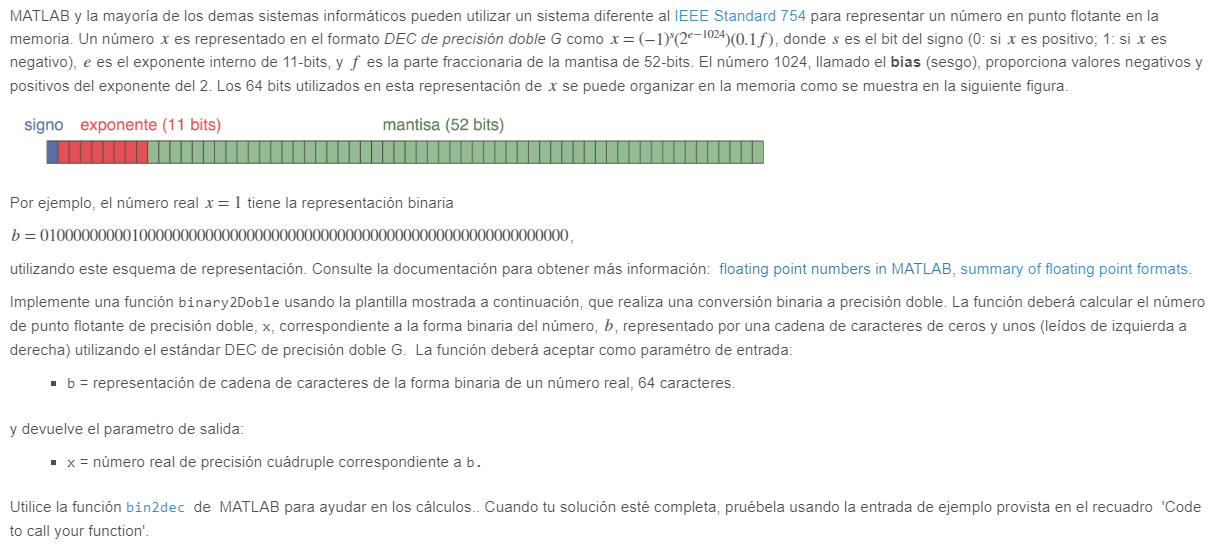

b ='0100000000001000000000000000000000000000000000000000000000000000';
x = binary2Double(b)

x = 0.7500

function x = binary2Doble(b)
    % Verifica si la cadena de entrada tiene 64 caracteres
    if numel(b) ~= 64
        error('La cadena de entrada debe tener 64 caracteres.');
    end
    
    % Obtener bits de signo, exponente y mantisa
    signBit = b(1);
    exponentBits = b(2:12);
    mantissaBits = b(13:64);
    
    % Convertir bits a valores decimales
    sign = (-1)^str2double(signBit);
    exponent = bin2dec(exponentBits) - 1023; % Restar el bias
    mantissa = 1 + bin2dec(mantissaBits) / 2^52; % Agregar el bit implícito
    
    % Calcular el valor decimal del número
    x = sign * mantissa * 2^exponent;
    
    x = x/4;
end


function [x] = binary2Double(b)
    s = bin2dec(b(1));
    e = bin2dec(b(2:12));
    m = b(13:64);

    E = e - 1023;
    M = bin2dec(m) / 2^-52;

    x = (-1)^s * (2^E) * (1 + M);
end